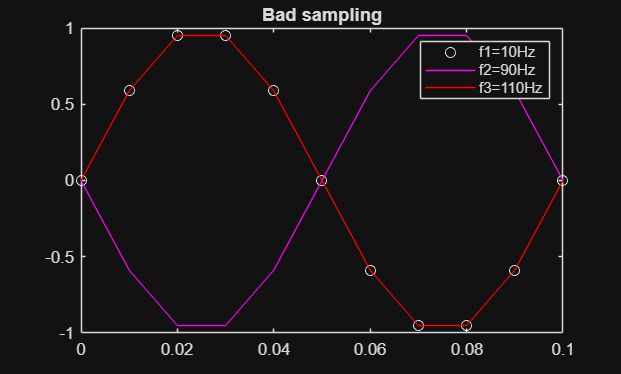

f1 = 10; f2 = 90; f3 = 110;
Ts = 0.01;
t = 0:Ts:0.1;
s1 = sin(2*pi*f1*t);
s2 = sin(2*pi*f2*t);
s3 = sin(2*pi*f3*t);
plot(t, s1, 'ow', t, s2, 'm-', t, s3, 'r-')
title('Bad sampling')
legend('f1=10Hz', 'f2=90Hz', 'f3=110Hz')

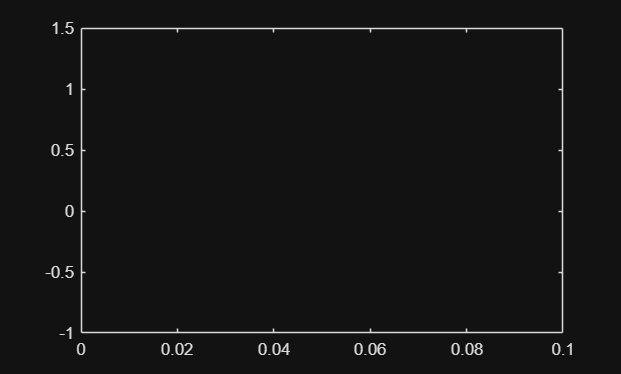

f1 = 10; f2 = 90; f3 = 110;

Ts = 0.01;
t = 0:Ts:0.1;
s1 = sin(2*pi*f1*t);
s2 = sin(2*pi*f2*t);
s3 = sin(2*pi*f3*t);
plot(t, s1, 'ok', t, s2, 'm-', t, s3, 'r-')
title('Bad sampling')
legend('f1=10Hz', 'f2=90Hz', 'f3=110Hz')

sgrid
close all
Ts = 1e-3;
n = 100;
r1 = zeros(1,n);

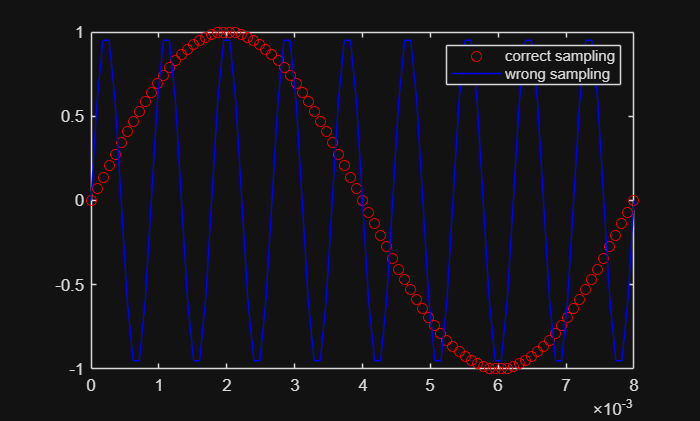

% alias frequency
Ts = 1e-3;
w1 = 0.25*pi/Ts;
w2 = 2.25*pi/Ts;
Ts = min([2*pi/w1 2*pi/w2])/10;
t = 0:Ts:2*pi/w1;
plot(t,sin(w1*t), 'or', t,sin(w2*t), 'b')
legend('correct sampling', 'wrong sampling')